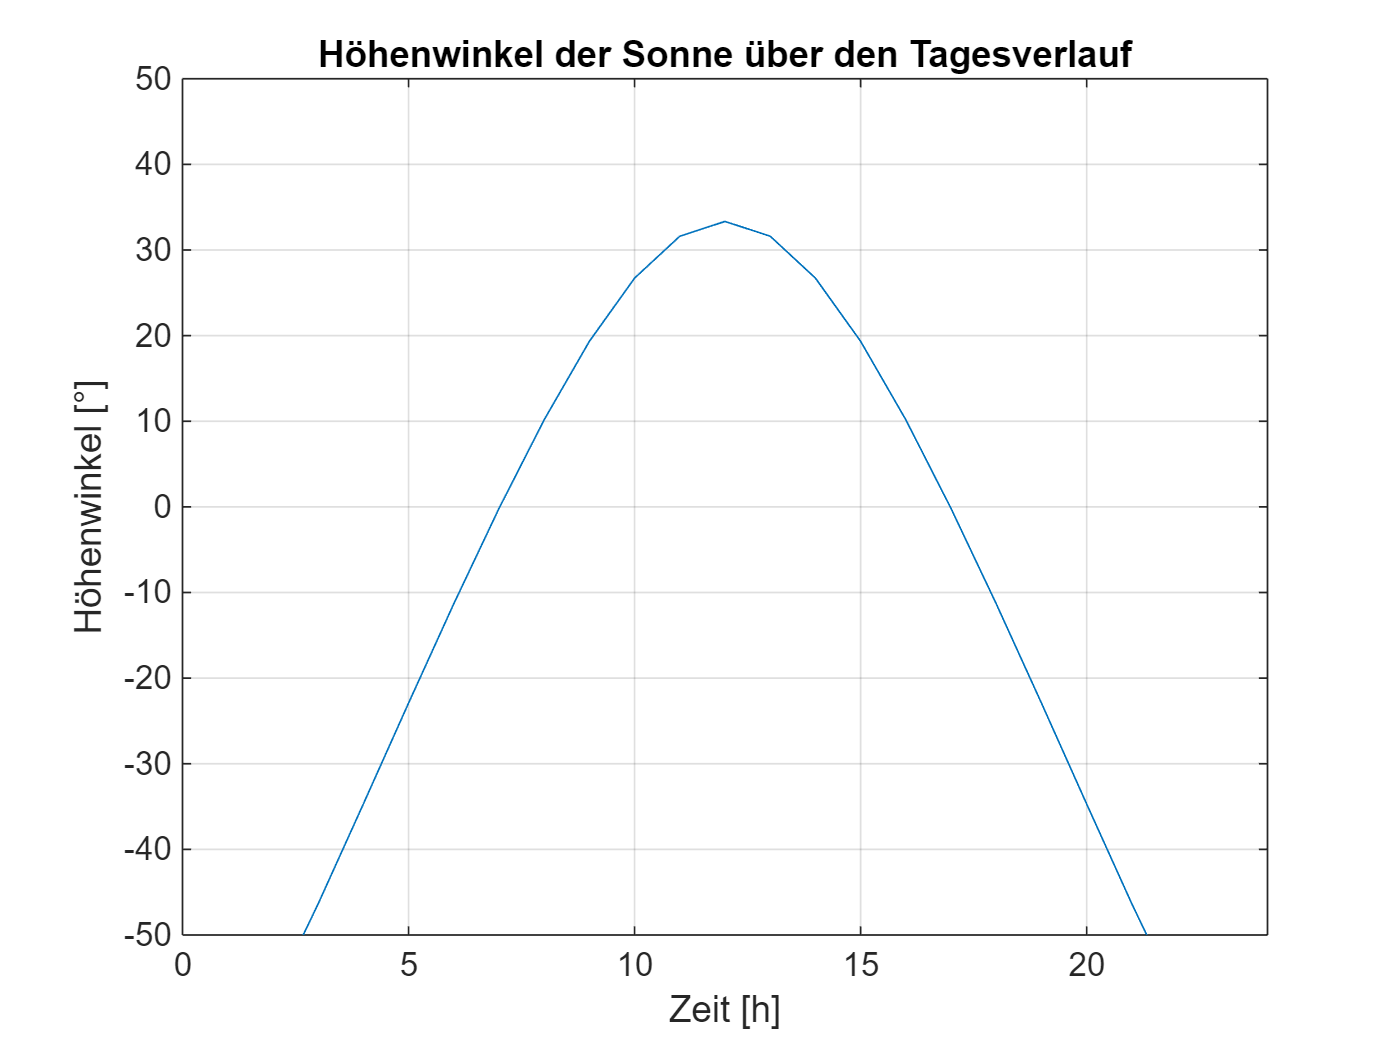

phi=38.1167; % geografische Breite von Palermo
t=0:1:24; % Tageszeiten
delta=Deklination(datetime('2025-01-28')); % Tag der Auswertung
H=Stundenwinkel(t);
a=Hoehenwinkel(phi,delta,t);
figure
plot(t,a)
xlabel("Zeit [h]");
ylabel("Höhenwinkel [°]");
title("Höhenwinkel der Sonne über den Tagesverlauf");
grid on;
ylim([-50 50]);
xlim([0 24]);

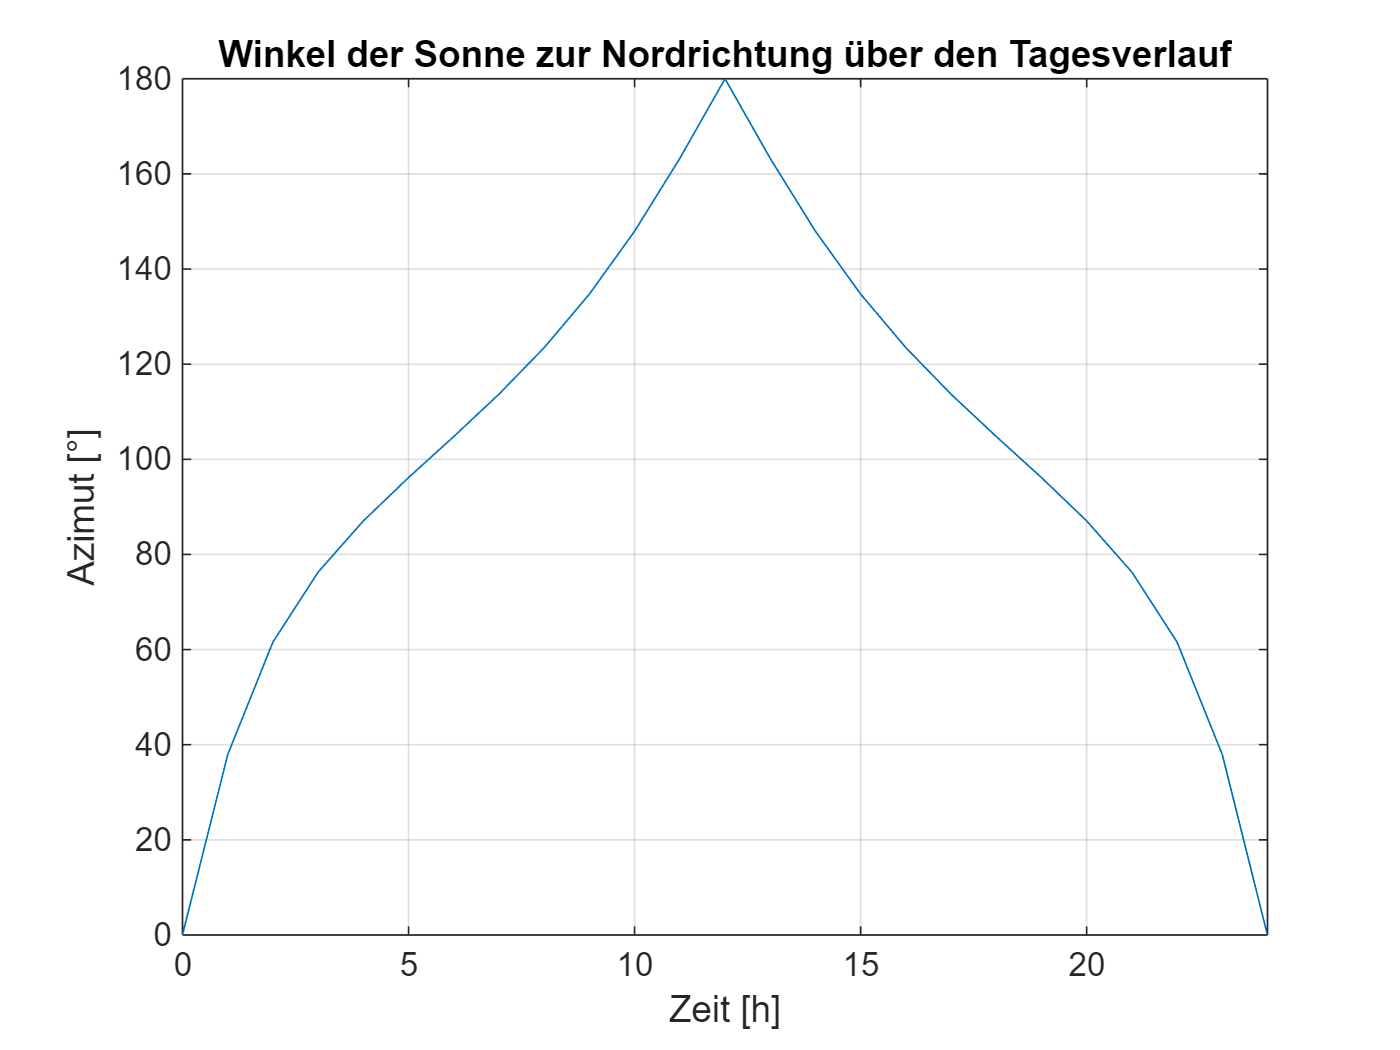


az=Azimut(delta,a,phi,t);
figure
plot(t,az)
xlabel("Zeit [h]");
ylabel("Azimut [°]");
title("Winkel der Sonne zur Nordrichtung über den Tagesverlauf");
grid on;
xlim([0 24]);

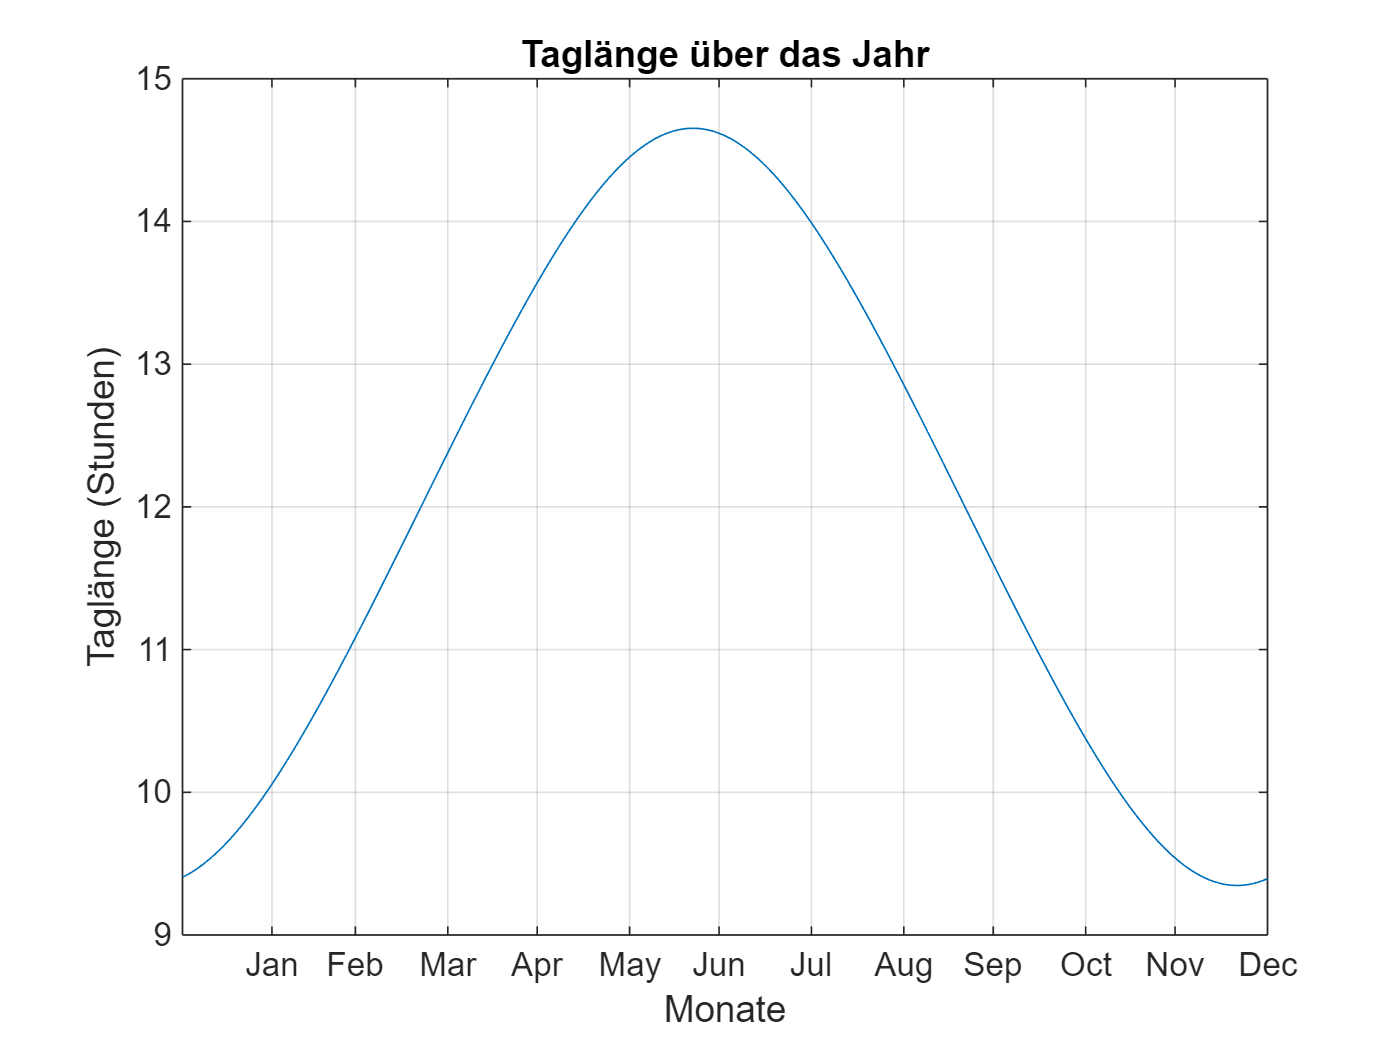


daylen=Taglaenge(phi);
figure
plot(1:365,daylen)
xlim([1,365]);
tage_pro_monat = [31, 28, 31, 30, 31, 30, 31, 31, 30, 31, 30, 31];
tage_am_monat_ende = cumsum(tage_pro_monat);
xticks(tage_am_monat_ende);
months = {'Jan', 'Feb', 'Mar', 'Apr', 'May', 'Jun', 'Jul', 'Aug', 'Sep', 'Oct', 'Nov', 'Dec'};
xticklabels(months);
xlabel('Monate');
ylabel('Taglänge (Stunden)');
title('Taglänge über das Jahr');
grid on;

Die Energie die eine Horizontal ausgerichtete PV-Anlage jeweils zum 21. der Monate März, Juni, September und Dezember in Elektrizität umwandelt.

horizontal_ausgerichtet = Horizontal_ausgerichtete(phi)

Error using datetime (line 257)
Could not recognize the date/time format of '21-März-2025'. You can specify a format using the 'InputFormat' parameter. If the date/time text contains day, month, or time zone names in a language foreign to the 'en_US' locale, those might not be recognized. You can specify a different locale using the 'Locale' parameter.

Error in Horizontal_ausgerichtete (